# ESERCITAZIONE___11/06/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili Simboliche 

syms x1 x2 x3 x4 dx1 dx2 dx3 dx4 u1 u2 real

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [x1;
     x2;
     x3;
     x4];

% Uscita
y = [x1;
     x3];

% Dimensioni
n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico Non lineare

eq_1_sym = dx1 == x2;
eq_2_sym = dx2 == -sin(x1) - 0.4*x2 + u1;
eq_3_sym = dx3 == x4;
eq_4_sym = dx4 == -0.5*sin(x3) - 0.3*x4 + u2 + 0.2*cos(x1);

eqs_sym = [eq_1_sym;
           eq_2_sym;
           eq_3_sym;
           eq_4_sym];

% dx/dt
f = [dx1;
     dx2;
     dx3;
     dx4];

% y
g = y;

## 1)  LINEARIZZAZIONE

#### Punto di Equilibrio

x_bar = zeros(n,1);
u_bar = [0;
         -0.2];

#### Verifica

peql_sym = subs(eqs_sym, [x; u], [x_bar; u_bar]);
peql = solve(peql_sym, f, "ReturnConditions",true);
dx = [peql.dx1;
      peql.dx2;
      peql.dx3;
      peql.dx4]

$$dx = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

#### Linearizzazione intorno a (x_bar,u_bar)

f_sym = solve(eqs_sym, [dx1, dx2, dx3, dx4], "ReturnConditions",true);

f = [f_sym.dx1;
     f_sym.dx2;
     f_sym.dx3;
     f_sym.dx4];

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_bar; u_bar]));
B = double(subs(B_sym, [x; u], [x_bar; u_bar]));
C = double(subs(C_sym, [x; u], [x_bar; u_bar]));
D = double(subs(D_sym, [x; u], [x_bar; u_bar]));

sys = ss(A, B, C, D)


sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    -1  -0.4     0     0
   x3     0     0     0     1
   x4     0     0  -0.5  -0.3
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Verifica Controllabilità e Osservabilità

Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


Autovalori di A

eig(A)

ans =   -0.2000 + 0.9798i
  -0.2000 - 0.9798i
  -0.1500 + 0.6910i
  -0.1500 - 0.6910i


## 2)  ASSEGNAMENTO AUTOVALORI CON METODO SI SYLVESTER

#### Specifiche

% Autovalori desiderati
eig_des = [-2, -3, -4, -5];

% Condizione iniziale
x0_sylv = [0.15;
           0;
           0.10;
           0];

#### Sintesi

Lambda = diag(eig_des)

Lambda =     -2     0     0     0
     0    -3     0     0
     0     0    -4     0
     0     0     0    -5



G = rand(m,n)

G =     0.5707    0.2860    0.7963    0.4462
    0.5718    0.6991    0.4416    0.4657



X = sylvester(A, -Lambda, -B*G);
K_eig = -G/X

K_eig =   -11.1076    0.4733   18.8551    5.7883
  -23.5022   -6.5087   31.4697   12.8267


A_cl_eig = A - B*K_eig;

disp(eig(A)); disp(eig(A_cl_eig));

  -0.2000 + 0.9798i
  -0.2000 - 0.9798i
  -0.1500 + 0.6910i
  -0.1500 - 0.6910i

   -2.0000
   -5.0000
   -3.0000
   -4.0000



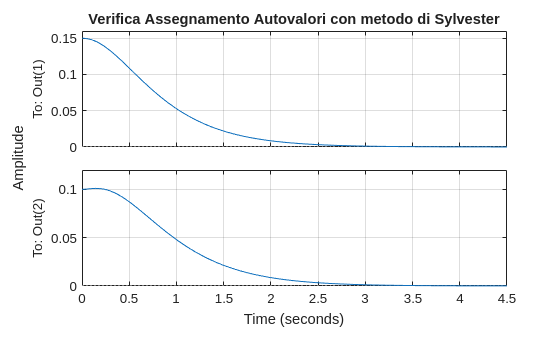


sys_eig = ss(A_cl_eig, B, C, D);

figure;
initial(sys_eig, x0_sylv);
grid on
title('Verifica Assegnamento Autovalori con metodo di Sylvester');

## 3)  REGOLATORE LQR CON AZIONE INTEGRATIVA

#### Specifiche 

% Riferimento
xref_lqr = [0.2;
            0.1];

% Tempo di Assestamento
Ts = 2;
alpha = 4/Ts;

% Sovraelongazione
max_ov_perc = 10;

#### Sistema Aumentato con l'errore di inseguimento su x1 e x3

n_aug = n+2;

C_LQR = [1, 0, 0, 0;
         0, 0, 1, 0];

A_aug = [A, zeros(n,2);
         -C_LQR, zeros(2,2)];

B_aug = [B;
         zeros(2,m)];

C_aug = [eye(n), zeros(n,2)];

D_aug = zeros(n,m);

sys_aug = ss(A_aug, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
         x1    x2    x3    x4    x5    x6
   x1     0     1     0     0     0     0
   x2    -1  -0.4     0     0     0     0
   x3     0     0     0     1     0     0
   x4     0     0  -0.5  -0.3     0     0
   x5    -1     0     0     0     0     0
   x6     0     0    -1     0     0     0
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
   x5   0   0
   x6   0   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


% Shift di A_aug per rispettare la specifica sul Ts
A_hat = A_aug + alpha*eye(n_aug);
sys_aug_shift = ss(A_hat, B_aug, C_aug, D_aug);

#### Sintesi

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 20*eye(2))

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0    20     0
     0     0     0     0     0    20


R = eye(m)

R =      1     0
     0     1


K_LQR = lqr(sys_aug_shift, Q, R)

K_LQR =    47.9480   11.5728    0.0000    0.0000  -68.5197   -0.0000
    0.0000   -0.0000   48.8498   11.7792   -0.0000  -68.4249


K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

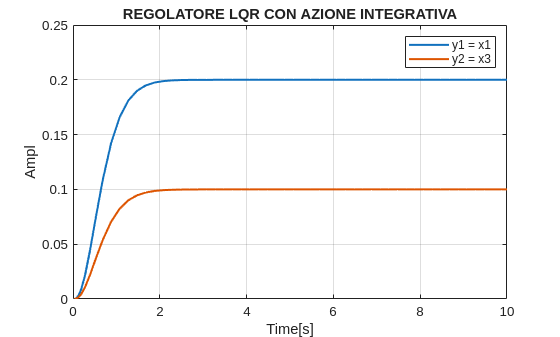

% Plot MATLAB
out = sim('LQR.slx');
y_lqr = out.y.Data;
time = out.y.Time;

figure
plot(time, y_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3');
title('REGOLATORE LQR CON AZIONE INTEGRATIVA');

## 4)  REGOLATORE LQG

#### Specifiche 

G = eye(n);

W = 0.01*eye(n);

V = 0.001*eye(m);

Qv = W;
Rv = V;

#### Regolatore LQR

Q = 100*eye(n);
R = 20*eye(m);

A_shift = A + alpha*eye(n);

sys_shift = ss(A_shift, B, C, D);
K_lqr_lqg = lqr(sys, Q, R)

K_lqr_lqg =     1.4495    2.4388   -0.0000    0.0000
    0.0000   -0.0000    1.7913    2.6449


#### Kalman Filter

sys_perturbato = ss(A, [B G], C, zeros(2,6))


sys_perturbato =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2    -1  -0.4     0     0
   x3     0     0     0     1
   x4     0     0  -0.5  -0.3
 
  B = 
       u1  u2  u3  u4  u5  u6
   x1   0   0   1   0   0   0
   x2   1   0   0   1   0   0
   x3   0   0   0   0   1   0
   x4   0   1   0   0   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2  u3  u4  u5  u6
   y1   0   0   0   0   0   0
   y2   0   0   0   0   0   0
 
Continuous-time state-space model.



% Guadagno di Kalman
[~, L, ~] = kalman(sys_perturbato, Qv, Rv);

A_kf = A - L*C;
B_kf = [B L];
C_kf = eye(n);
D_kf = zeros(n,size(B_kf,2));

KF = ss(A_kf, B_kf, C_kf, D_kf)


KF =
 
  A = 
               x1          x2          x3          x4
   x1      -3.506           1   4.193e-15           0
   x2      -2.147        -0.4  -6.558e-16           0
   x3  -2.664e-16           0      -3.671           1
   x4  -1.598e-15           0      -2.238        -0.3
 
  B = 
               u1          u2          u3          u4
   x1           0           0       3.506  -4.193e-15
   x2           1           0       1.147   6.558e-16
   x3           0           0   2.664e-16       3.671
   x4           0           1   1.598e-15       1.738
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   0   0   0   0
   y2   0   0   0   0
   y3   0   0   0   0
   y4   0   0   0   0
 
Continuous-time state-space model.


#### Compensazione del guadagno

A_cl_kf = A - B*K_lqr_lqg;

sys_cl_lqg = ss(A_cl_kf, B, C, D);

gain_cl_lqg = dcgain(sys_cl_lqg);

N_lqg = pinv(gain_cl_lqg)

N_lqg =     2.4495   -0.0000
    0.0000    2.2913


#### Verifica Simulazione

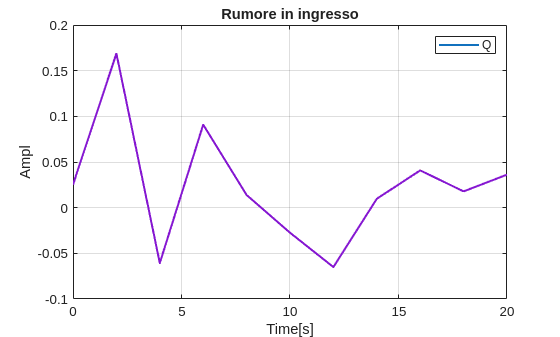

% Plot MATLAB
out = sim('LQG.slx');
y_lqg = out.y.Data;
ref = out.r.Data;
Q_lqg = out.Q.Data;
R_lqg = out.R.Data;
time = out.y.Time;
noise_time = out.Q.Time;

figure

plot(noise_time, Q_lqg, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('Q');
title('Rumore in ingresso');

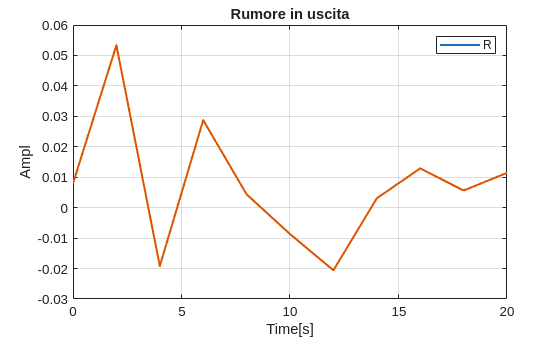

plot(noise_time, R_lqg, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('R');
title('Rumore in uscita');

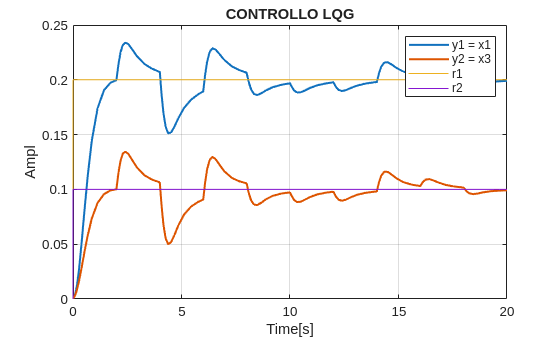

plot(time, y_lqg, "LineWidth", 1.5);
grid on
hold on
plot(time, ref, "LineWidth", 0.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3', 'r1', 'r2');
title('CONTROLLO LQG');